clear
clf

data = readmatrix('aerobic_tests.csv');
data_dim = size(data);
num_datapoints = data_dim(1);
addpath ../ % for access to fit_data function

% label data from csv
% exclude first data point
time = data(2:num_datapoints, 1) / 60;     % hours
A = data(2:num_datapoints, 2); % optical density
B = data(2:num_datapoints, 3); % optical density
C = data(2:num_datapoints, 4); % optical density
D = data(2:num_datapoints, 5); % optical density
E = data(2:num_datapoints, 6); % optical density
F = data(2:num_datapoints, 7); % optical density
G = data(2:num_datapoints, 8); % optical density
H = data(2:num_datapoints, 9); % optical density
I = data(2:num_datapoints, 10);% optical density
J = data(2:num_datapoints, 11);% optical density
K = data(2:num_datapoints, 12);% optical density
L = data(2:num_datapoints, 13);% optical density
M = data(2:num_datapoints, 14);% optical density
N = data(2:num_datapoints, 15);% optical density

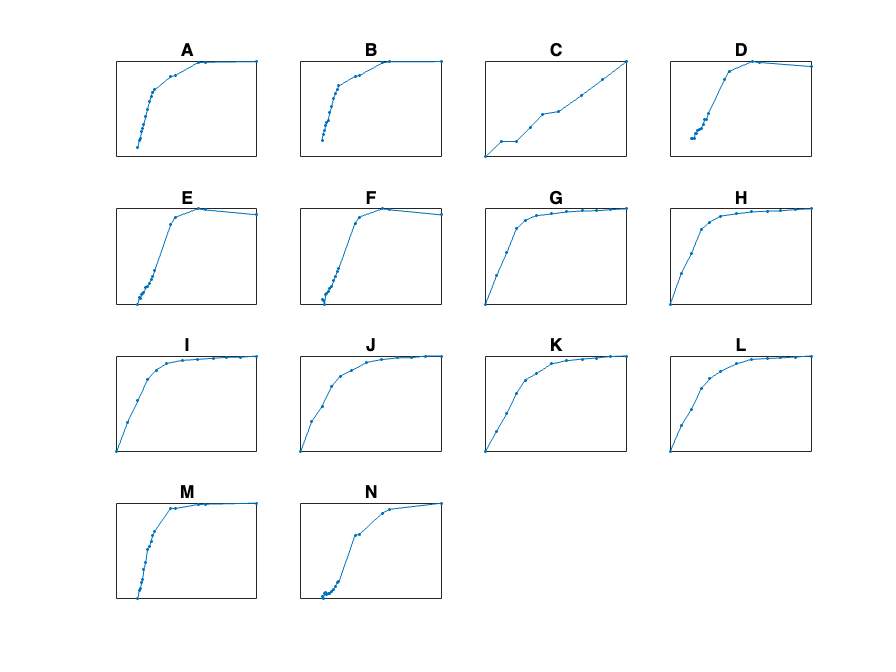

% For quick visualization purposes. Optical density on vertical axis,
% time in hours on horizontal axis. Note that the horizontal axes are
% consistent between graphs, but the vertical axes are not


% I know this is ugly and inefficient but it does the job and I am
% very tired.

clf
figure
subplot(4,4,1)
semilogy(time, A, '.-');
set(gca,'XTick',[], 'YTick', [])
title("A")
hold on
subplot(4,4,2)
semilogy(time, B, '.-');
title("B")
set(gca,'XTick',[], 'YTick', [])
subplot(4,4,3)
semilogy(time, C, '.-');
title("C")
set(gca,'XTick',[], 'YTick', [])
subplot(4,4,4)
semilogy(time, D, '.-');
title("D")
set(gca,'XTick',[], 'YTick', [])
subplot(4,4,5)
semilogy(time, E, '.-');
title("E")
set(gca,'XTick',[], 'YTick', [])
subplot(4,4,6)
semilogy(time, F, '.-');
title("F")
set(gca,'XTick',[], 'YTick', [])
subplot(4,4,7)
semilogy(time, G, '.-');
title("G")
set(gca,'XTick',[], 'YTick', [])
subplot(4,4,8)
semilogy(time, H, '.-');
title("H")
set(gca,'XTick',[], 'YTick', [])
subplot(4,4,9)
semilogy(time, I, '.-');
title("I")
set(gca,'XTick',[], 'YTick', [])
subplot(4,4,10)
semilogy(time, J, '.-');
title("J")
set(gca,'XTick',[], 'YTick', [])
subplot(4,4,11)
semilogy(time, K, '.-');
title("K")
set(gca,'XTick',[], 'YTick', [])
subplot(4,4,12)
semilogy(time, L, '.-');
title("L")
set(gca,'XTick',[], 'YTick', [])
subplot(4,4,13)
semilogy(time, M, '.-');
title("M")
set(gca,'XTick',[], 'YTick', [])
subplot(4,4,14)
semilogy(time, N, '.-');
title("N")
set(gca,'XTick',[], 'YTick', [])

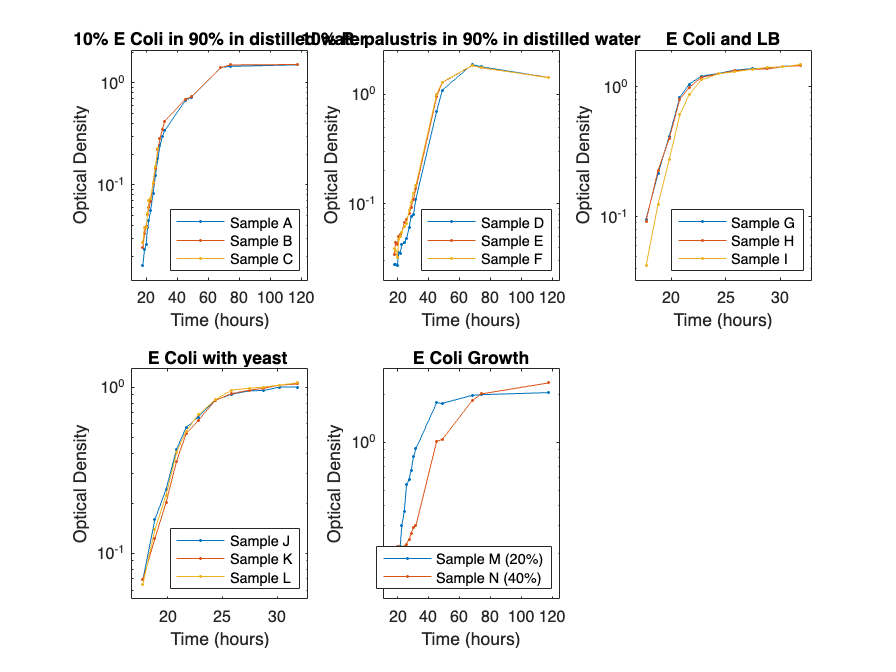

% Growth graphs separated into groups w/ same setup
% E Coli 10% in 90% in distilled water
clf
figure
subplot(2,3,1)
semilogy(time, A, '.-');
hold on
semilogy(time, B, '.-');
semilogy(time, C, '.-');
title("10% E Coli in 90% in distilled water")
xlabel("Time (hours)")
ylabel("Optical Density")
legend("Sample A","Sample B","Sample C", ...
    "location", "southeast")
axis padded
hold off

% R plaus 10% in 90% in distilled water
subplot(2,3,2)
semilogy(time, D, '.-');
hold on
semilogy(time, E, '.-');
semilogy(time, F, '.-');
title("10% R. palustris in 90% in distilled water")
xlabel("Time (hours)")
ylabel("Optical Density")
legend("Sample D","Sample E","Sample F", ...
    "location", "southeast")
axis padded
hold off

% E Coli and LB
subplot(2,3,3)
semilogy(time, G, '.-');
hold on
semilogy(time, H, '.-');
semilogy(time, I, '.-');
title("E Coli and LB")
xlabel("Time (hours)")
ylabel("Optical Density")
legend("Sample G","Sample H","Sample I", ...
    "location", "southeast")
axis padded
hold off

% E Coli with yeast 
subplot(2,3,4)
semilogy(time, J, '.-');
hold on
semilogy(time, K, '.-');
semilogy(time, L, '.-');
title("E Coli with yeast ")
xlabel("Time (hours)")
ylabel("Optical Density")
legend("Sample J","Sample K","Sample L", ...
    "location", "southeast")
axis padded
hold off

% E Coli 20% and 40%
subplot(2,3,5)
semilogy(time, M, '.-');
hold on
semilogy(time, N, '.-');
title("E Coli Growth")
xlabel("Time (hours)")
ylabel("Optical Density")
legend("Sample M (20%)","Sample N (40%)",...
    "location", "southeast")
axis padded
hold off

## Sample A

isolate_A = 1:12;
[fitA, gofA, growthrate_A, yieldA] = fit_data(A, isolate_A, time)

fitA =      General model Exp1:
     fitA(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =    0.001026  (0.0001799, 0.001873)
       b =      0.1848  (0.1572, 0.2124)

gofA = struct with fields:
           sse: 0.0035
       rsquare: 0.9756
           dfe: 10
    adjrsquare: 0.9731
          rmse: 0.0188


growthrate_A = 3.7515

yieldA = 1.4840

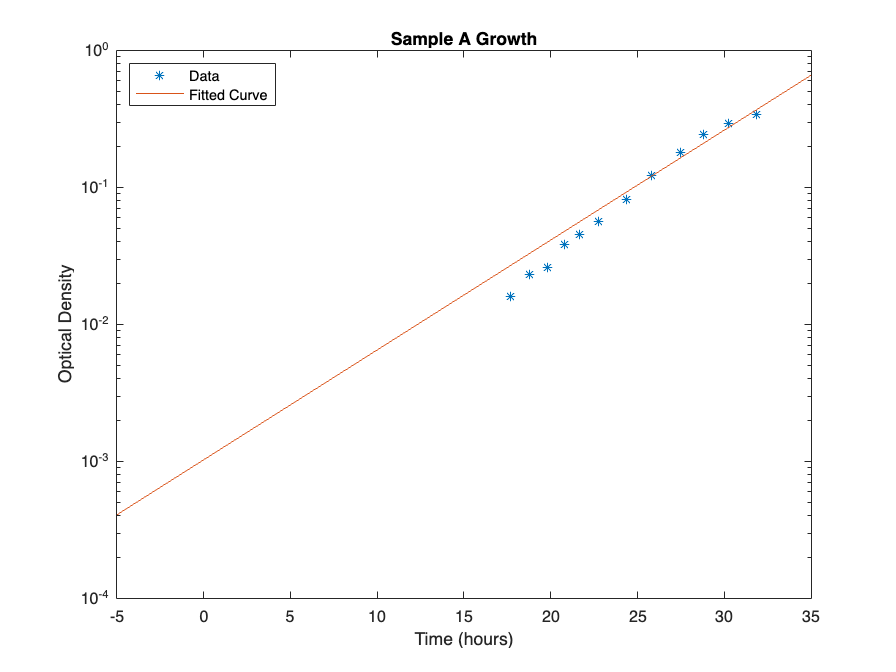

title("Sample A Growth")

## Sample B

isolate_B = 1:11;
[fitB, gofB, growthrate_B, yieldB] = fit_data(B, isolate_B, time)

fitB =      General model Exp1:
     fitB(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =   0.0007318  (0.0003894, 0.001074)
       b =      0.2051  (0.1887, 0.2215)

gofB = struct with fields:
           sse: 7.9752e-04
       rsquare: 0.9935
           dfe: 9
    adjrsquare: 0.9928
          rmse: 0.0094


growthrate_B = 3.3796

yieldB = 1.4880

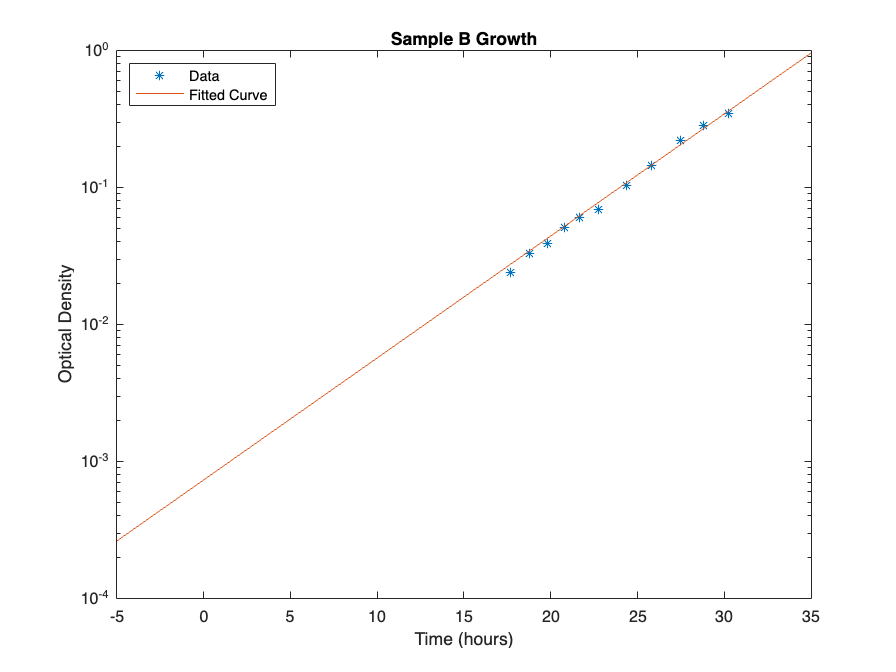

title("Sample B Growth")

## Sample C

Note that data collection for sample C ended was truncated due to a leak in the test tube.

isolate_C = 1:9;
[fitC, gofC, growthrate_C, yieldC] = fit_data(C, isolate_C, time)

fitC =      General model Exp1:
     fitC(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =   0.0005009  (0.000276, 0.0007257)
       b =       0.222  (0.2047, 0.2394)

gofC = struct with fields:
           sse: 1.8942e-04
       rsquare: 0.9944
           dfe: 7
    adjrsquare: 0.9936
          rmse: 0.0052


growthrate_C = 3.1216

yieldC = 0.1990

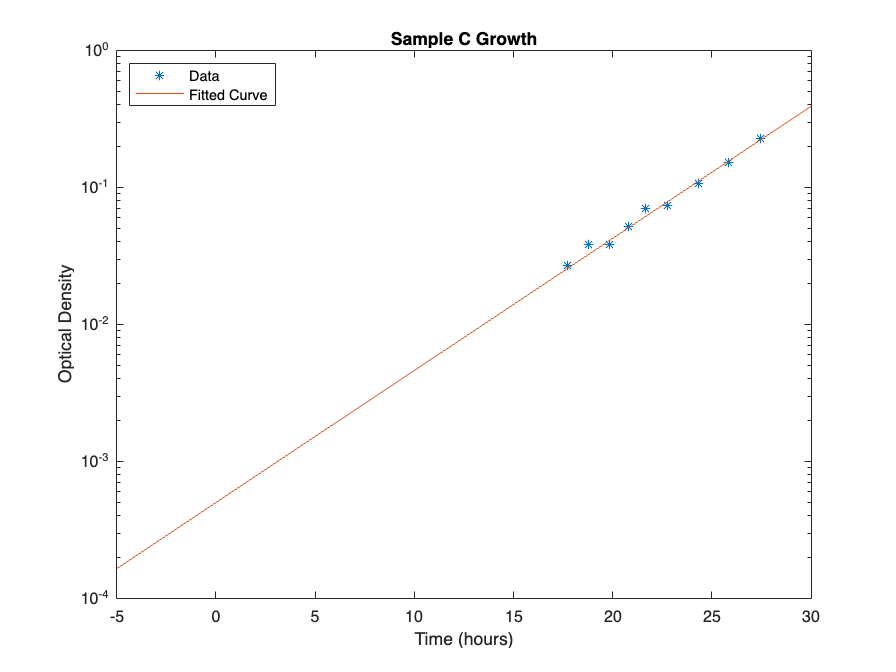

title("Sample C Growth")

## Sample D

isolate_D = 1:14;
[fitD, gofD, growthrate_D, yieldD] = fit_data(D, isolate_D, time)

fitD =      General model Exp1:
     fitD(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =    0.001846  (0.00146, 0.002233)
       b =      0.1305  (0.1261, 0.1349)

gofD = struct with fields:
           sse: 9.9778e-04
       rsquare: 0.9992
           dfe: 12
    adjrsquare: 0.9992
          rmse: 0.0091


growthrate_D = 5.3095

yieldD = 1.8420

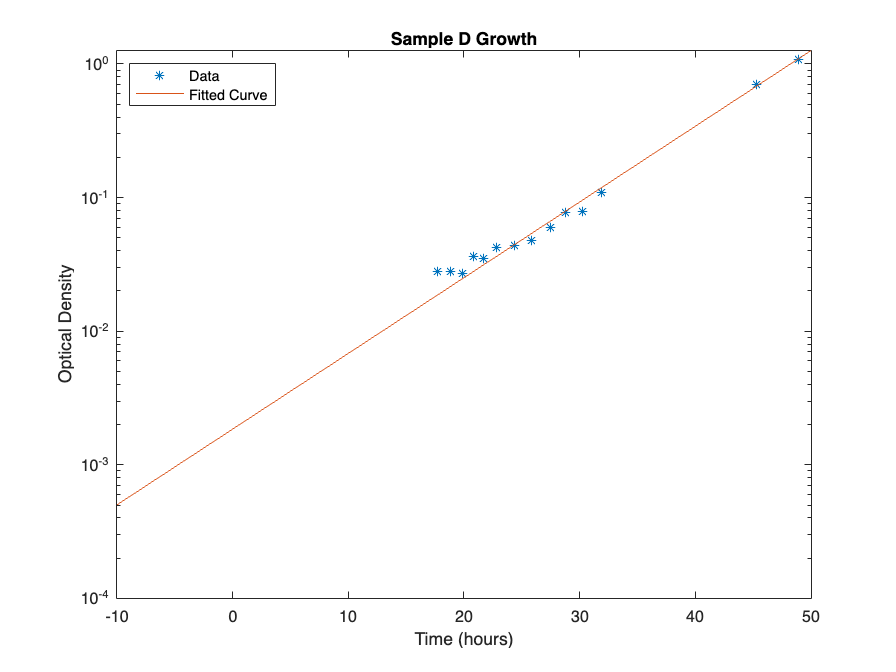

title("Sample D Growth")

## Sample E

isolate_E = 1:14;
[fitE, gofE, growthrate_E, yieldE] = fit_data(E, isolate_E, time)

fitE =      General model Exp1:
     fitE(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =    0.003691  (0.001721, 0.005661)
       b =      0.1203  (0.109, 0.1316)

gofE = struct with fields:
           sse: 0.0137
       rsquare: 0.9929
           dfe: 12
    adjrsquare: 0.9923
          rmse: 0.0338


growthrate_E = 5.7624

yieldE = 1.7950

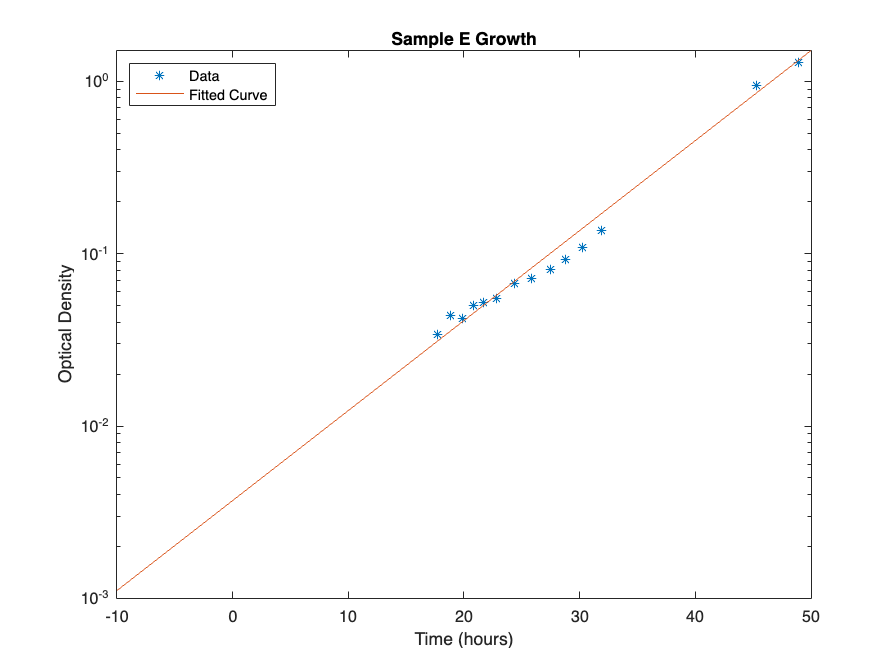

title("Sample E Growth")

## Sample F

isolate_F = 1:14;
[fitF, gofF, growthrate_F, yieldF] = fit_data(F, isolate_F, time)

fitF =      General model Exp1:
     fitF(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =    0.004187  (0.001584, 0.00679)
       b =      0.1181  (0.105, 0.1313)

gofF = struct with fields:
           sse: 0.0210
       rsquare: 0.9897
           dfe: 12
    adjrsquare: 0.9888
          rmse: 0.0418


growthrate_F = 5.8686

yieldF = 1.8010

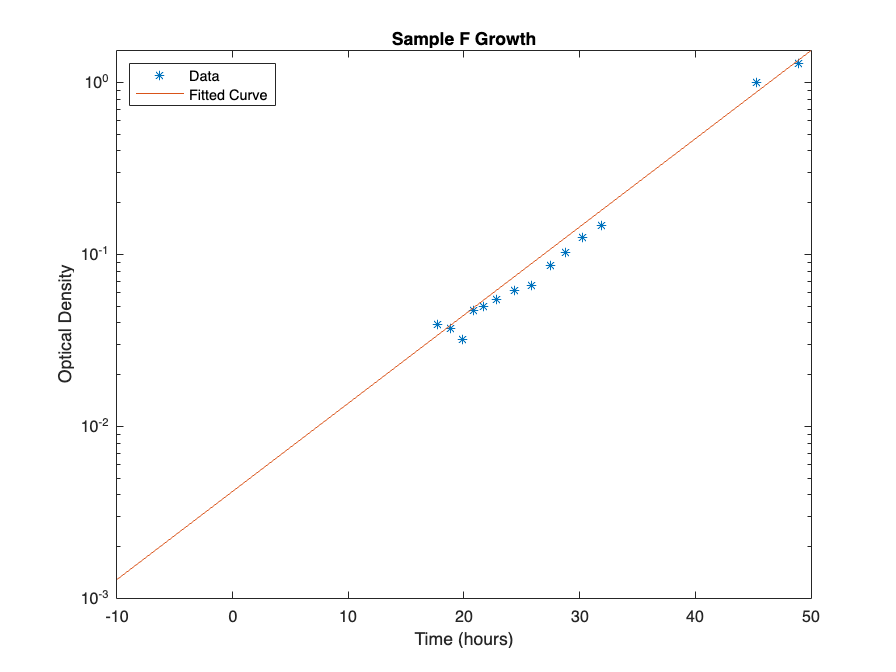

title("Sample F Growth")

## Sample G

isolate_G = 1:4;
[fitG, gofG, growthrate_G, yieldG] = fit_data(G, isolate_G, time)

fitG =      General model Exp1:
     fitG(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =   4.567e-07  (-2.046e-08, 9.338e-07)
       b =       0.693  (0.642, 0.744)

gofG = struct with fields:
           sse: 9.5780e-05
       rsquare: 0.9997
           dfe: 2
    adjrsquare: 0.9995
          rmse: 0.0069


growthrate_G = 1.0002

yieldG = 1.3780

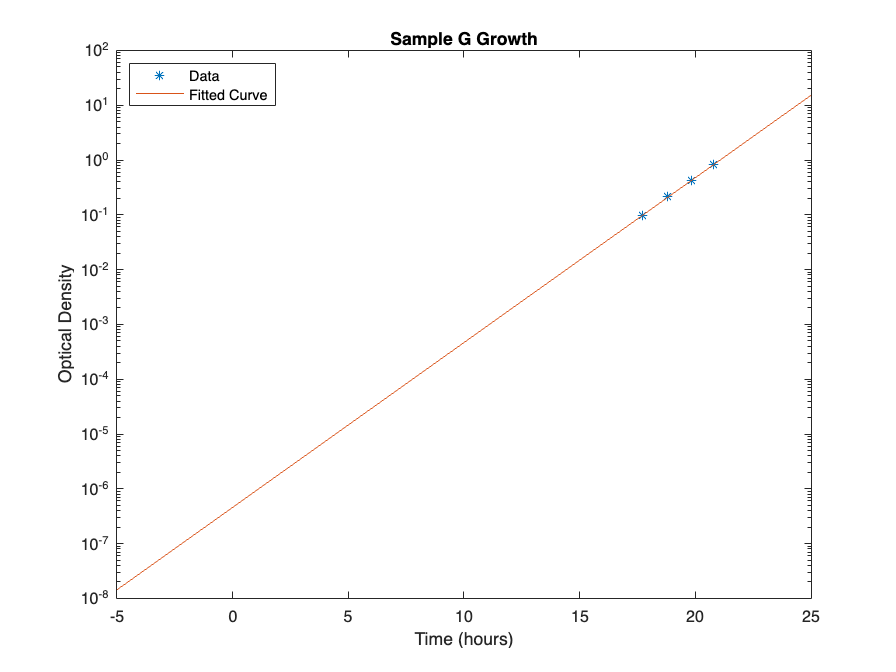

title("Sample G Growth")

## Sample H

isolate_H = 1:4;
[fitH, gofH, growthrate_H, yieldH] = fit_data(H, isolate_H, time)

fitH =      General model Exp1:
     fitH(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =   6.531e-07  (-1.096e-06, 2.402e-06)
       b =      0.6741  (0.5433, 0.8048)

gofH = struct with fields:
           sse: 6.2258e-04
       rsquare: 0.9978
           dfe: 2
    adjrsquare: 0.9967
          rmse: 0.0176


growthrate_H = 1.0283

yieldH = 1.3670

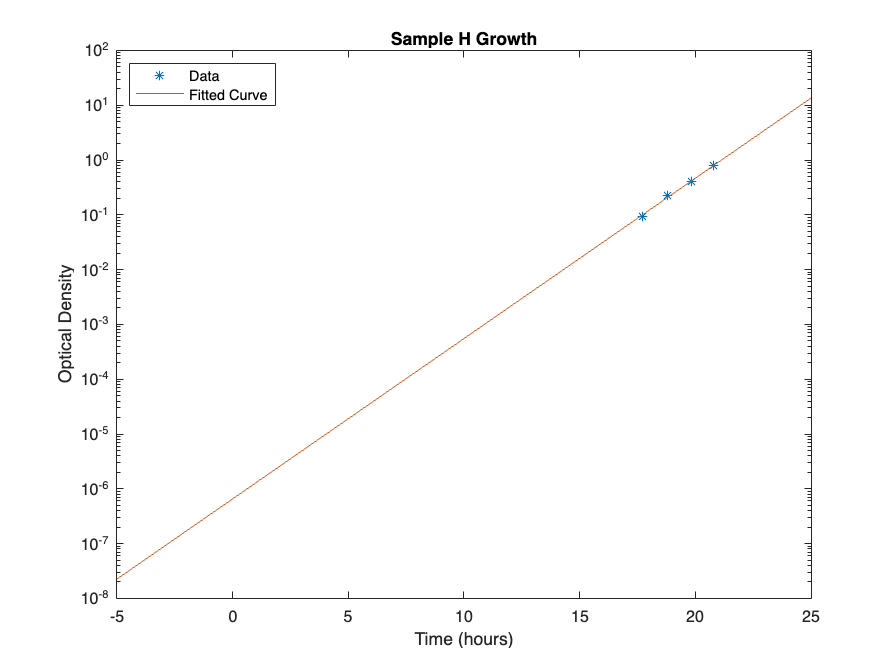

title("Sample H Growth")

## Sample I

isolate_I = 1:4;
[fitI, gofI, growthrate_I, yieldI] = fit_data(I, isolate_I, time)

fitI =      General model Exp1:
     fitI(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =   2.644e-08  (-1.406e-08, 6.694e-08)
       b =      0.8152  (0.7407, 0.8897)

gofI = struct with fields:
           sse: 7.5572e-05
       rsquare: 0.9996
           dfe: 2
    adjrsquare: 0.9994
          rmse: 0.0061


growthrate_I = 0.8503

yieldI = 1.4460

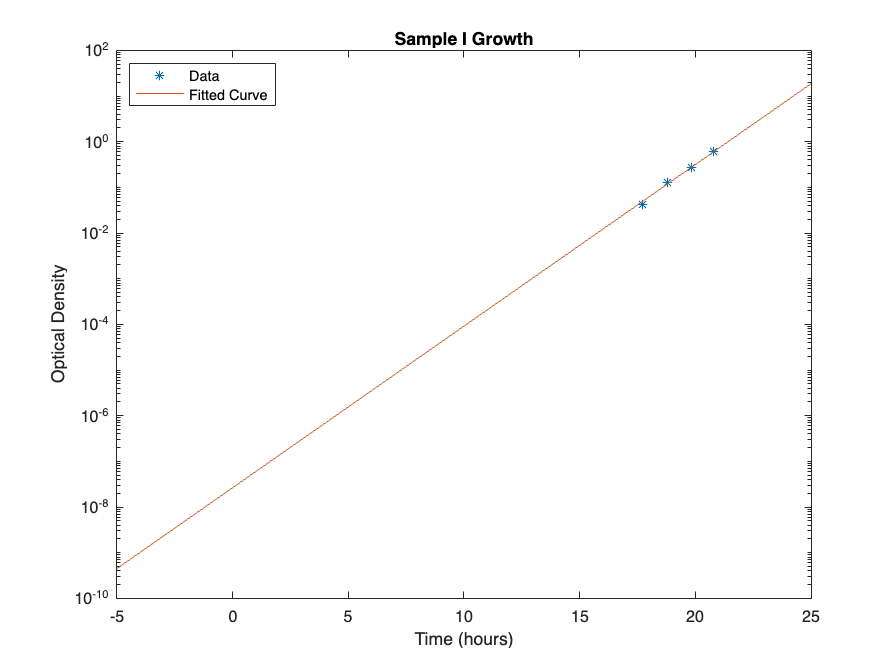

title("Sample I Growth")

## Sample J

isolate_J = 1:4;
[fitJ, gofJ, growthrate_J, yieldJ] = fit_data(J, isolate_J, time)

fitJ =      General model Exp1:
     fitJ(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =   5.618e-06  (-1.271e-05, 2.394e-05)
       b =      0.5398  (0.3796, 0.7)

gofJ = struct with fields:
           sse: 4.0650e-04
       rsquare: 0.9941
           dfe: 2
    adjrsquare: 0.9911
          rmse: 0.0143


growthrate_J = 1.2840

yieldJ = 0.9320

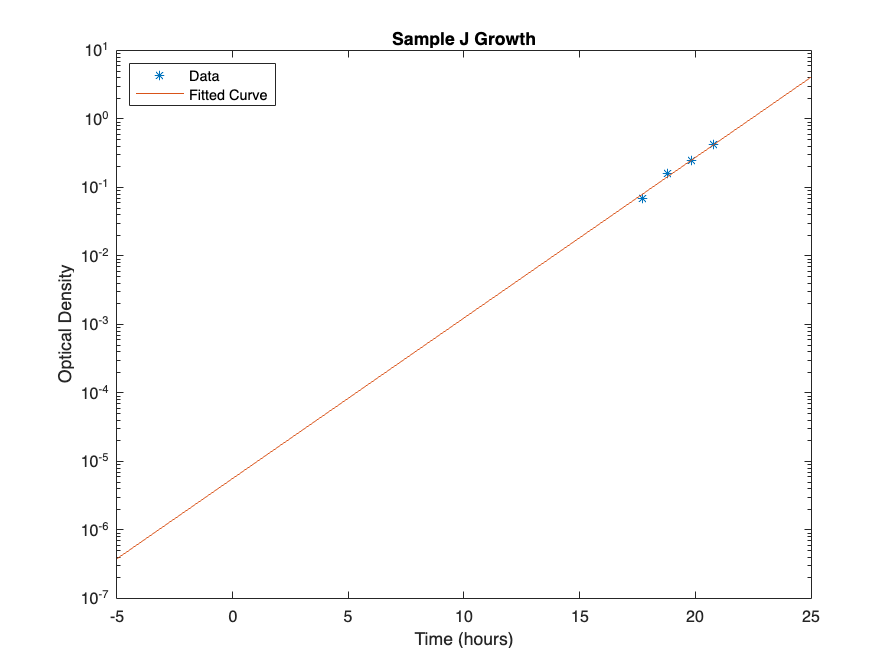

title("Sample J Growth")

## Sample K

isolate_K = 1:5;
[fitK, gofK, growthrate_K, yieldK] = fit_data(K, isolate_K, time)

fitK =      General model Exp1:
     fitK(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =   9.268e-06  (-3.353e-06, 2.189e-05)
       b =      0.5057  (0.4413, 0.5701)

gofK = struct with fields:
           sse: 3.8419e-04
       rsquare: 0.9972
           dfe: 3
    adjrsquare: 0.9963
          rmse: 0.0113


growthrate_K = 1.3707

yieldK = 0.9750

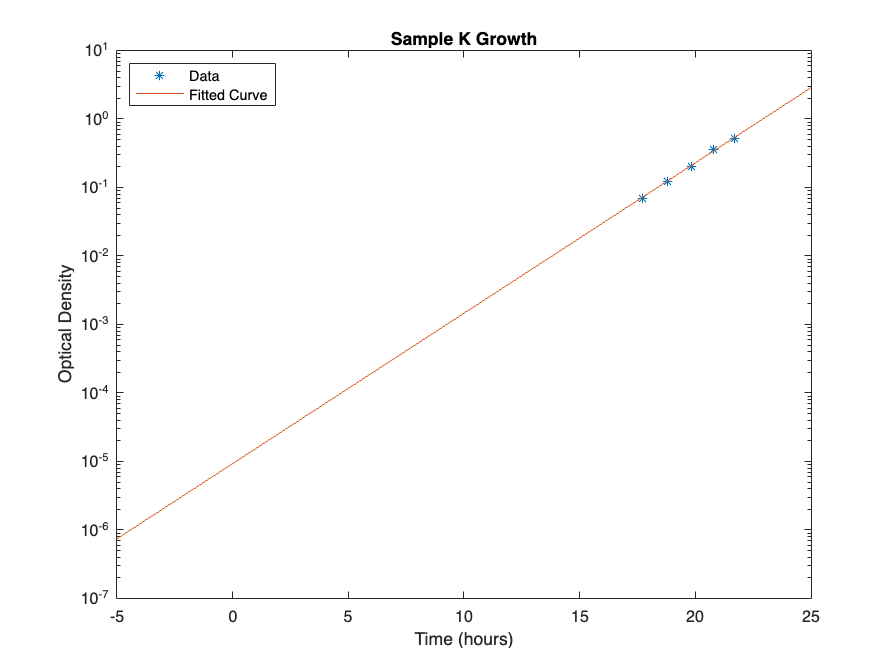

title("Sample K Growth")

## Sample J

isolate_J = 1:4;
[fitJ, gofJ, growthrate_J, yieldJ] = fit_data(J, isolate_J, time)

fitJ =      General model Exp1:
     fitJ(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =   5.618e-06  (-1.271e-05, 2.394e-05)
       b =      0.5398  (0.3796, 0.7)

gofJ = struct with fields:
           sse: 4.0650e-04
       rsquare: 0.9941
           dfe: 2
    adjrsquare: 0.9911
          rmse: 0.0143


growthrate_J = 1.2840

yieldJ = 0.9320

title("Sample J Growth")

## Sample K

isolate_K = 1:5;
[fitK, gofK, growthrate_K, yieldK] = fit_data(K, isolate_K, time)

fitK =      General model Exp1:
     fitK(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =   9.268e-06  (-3.353e-06, 2.189e-05)
       b =      0.5057  (0.4413, 0.5701)

gofK = struct with fields:
           sse: 3.8419e-04
       rsquare: 0.9972
           dfe: 3
    adjrsquare: 0.9963
          rmse: 0.0113


growthrate_K = 1.3707

yieldK = 0.9750

title("Sample K Growth")

## Sample L

isolate_L = 1:4;
[fitL, gofL, growthrate_L, yieldL] = fit_data(L, isolate_L, time)

fitL =      General model Exp1:
     fitL(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =   2.667e-06  (-3.645e-06, 8.979e-06)
       b =      0.5735  (0.4574, 0.6895)

gofL = struct with fields:
           sse: 1.7381e-04
       rsquare: 0.9973
           dfe: 2
    adjrsquare: 0.9960
          rmse: 0.0093


growthrate_L = 1.2087

yieldL = 0.9950

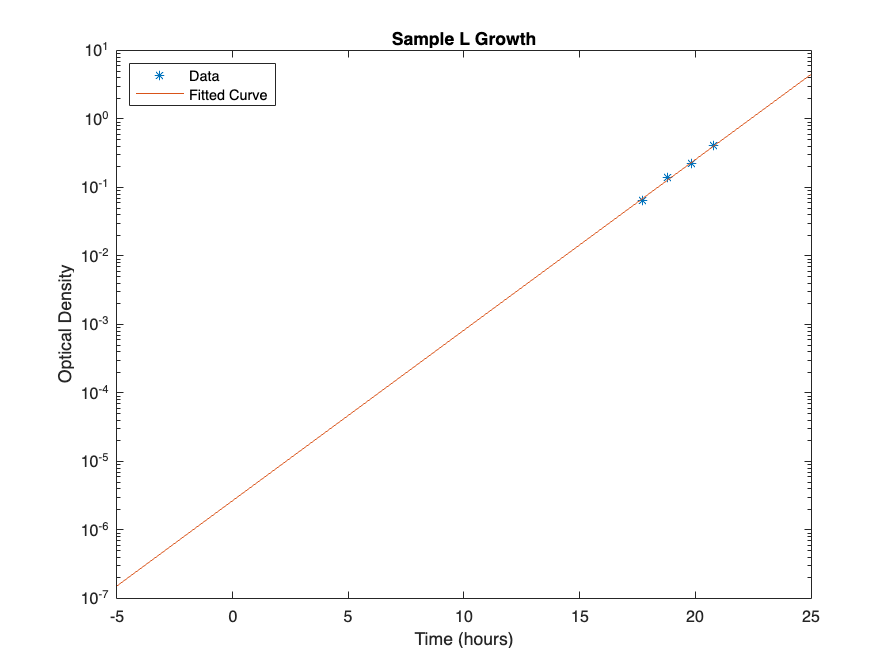

title("Sample L Growth")

## Sample M

isolate_M = 1:12;
[fitM, gofM, growthrate_M, yieldM] = fit_data(M, isolate_M, time)

fitM =      General model Exp1:
     fitM(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =     0.01628  (0.008458, 0.0241)
       b =      0.1282  (0.1116, 0.1449)

gofM = struct with fields:
           sse: 0.0196
       rsquare: 0.9760
           dfe: 10
    adjrsquare: 0.9736
          rmse: 0.0442


growthrate_M = 5.4058

yieldM = 1.9140

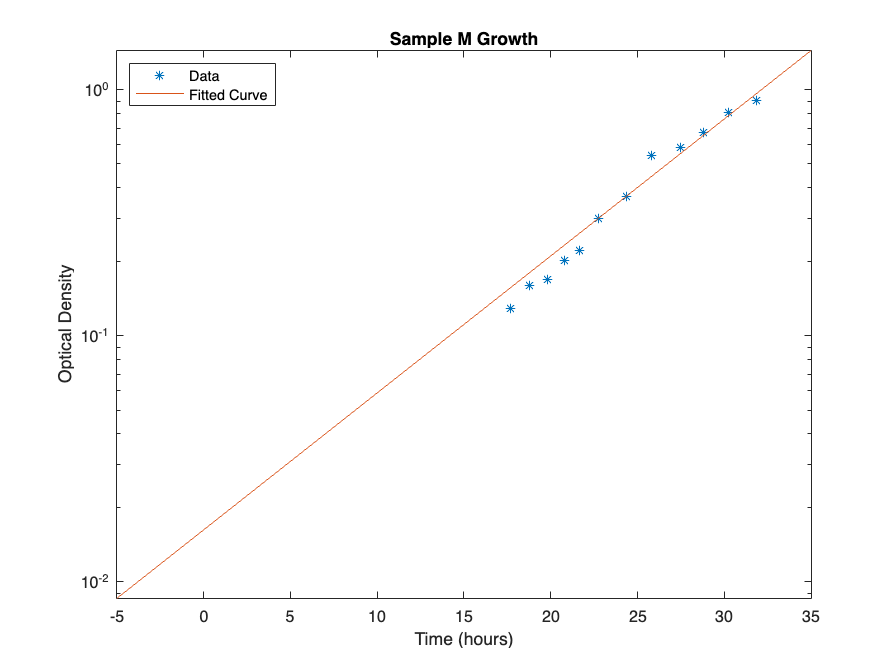

title("Sample M Growth")

## Sample N

isolate_N = 7:14;
[fitN, gofN, growthrate_N, yieldN] = fit_data(N, isolate_N, time)

fitN =      General model Exp1:
     fitN(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =     0.03884  (0.01367, 0.06402)
       b =      0.0688  (0.05432, 0.08329)

gofN = struct with fields:
           sse: 0.0291
       rsquare: 0.9672
           dfe: 6
    adjrsquare: 0.9617
          rmse: 0.0696


growthrate_N = 10.0746

yieldN = 2.1560

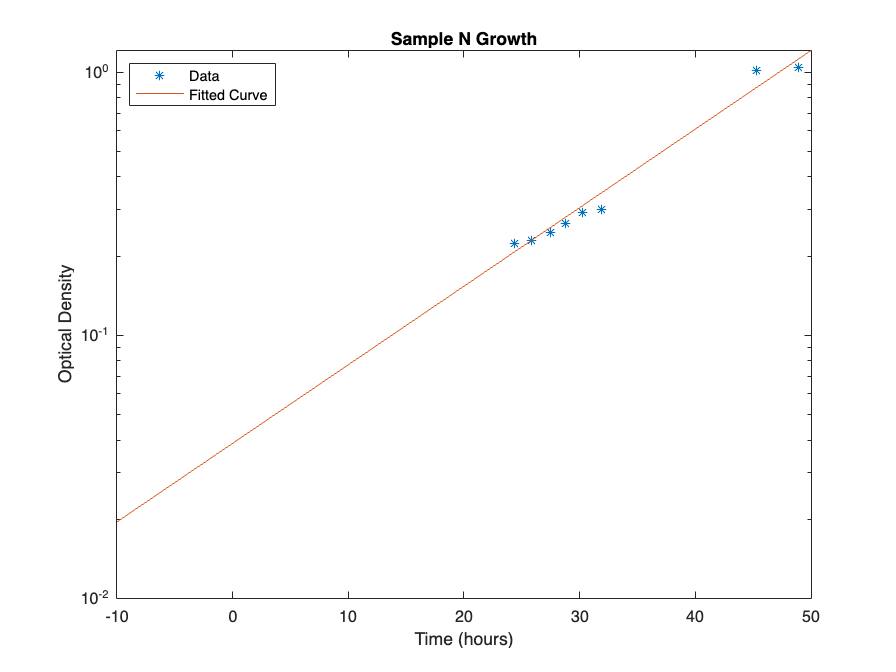

title("Sample N Growth")

## Growth Rates


$$\matrix{
\text{Sample}    	& A & B & C & D & E & F & G & H  & I & J & K & L & M & N   \cr
\text{Growth Rate} & 3.75 & 3.38 & 3.12 & 5.31 & 5.76 & 5.89 &  1.00 & 1.03 & 0.85 & 1.28 & 1.37 & 1.21 & 5.41 & 10.07
}$$


## Yields


$$\matrix{
\text{Sample}    	& A & B & C & D & E & F & G & H  & I & J & K & L & M & N   \cr
\text{Yield} & 1.48 & 1.48 & 0.20 & 1.84 & 1.80 & 1.80 & 1.38 & 1.37 & 1.45 & 0.93 & 0.98 & 1.00 & 1.91 & 2.16 \cr
}$$
